# 2D Ball Example

### Problem Setup

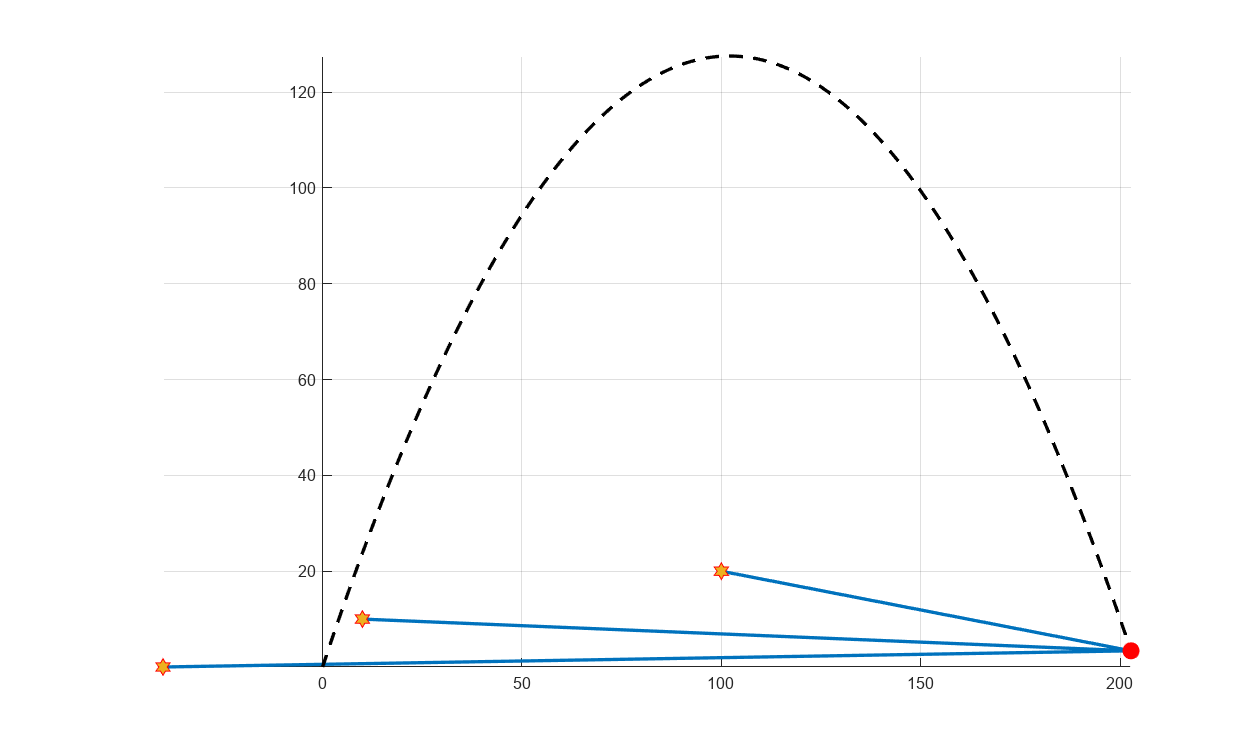

numSteps = 150;
x0 = [0; 0; 20; 50];
g = 9.8;

[xRecTru, t] = getTraj(x0,g,numSteps);

figure;
axis tight
grid on
set(gcf,'Position',[100 100 1000 600],'color','w');
set(gca,'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
hold on

senObs = [10 10; 100 20 ;-40 0]; % sensor posistion

%%% static plotting
for ss=1:size(senObs,1)
    hLine(ss) = line([senObs(ss,1), xRecTru(1,1)],[senObs(ss,2), xRecTru(2,1)],'lineWidth',2);
    plot(senObs(ss,1),senObs(ss,2),'h','MarkerSize', 10,'MarkerFaceColor','#EDB120','MarkerEdgeColor','red');
end

plot(xRecTru(1,:),xRecTru(2,:),'LineWidth',2,'LineStyle','--','Color','k');

% init of dynamic objects
ballMarker = plot(xRecTru(1,1),xRecTru(2,1),'Marker','.','MarkerSize',35,'Color','r');

for ii=2:numSteps
    ballMarker.XData = xRecTru(1,ii);
    ballMarker.YData = xRecTru(2,ii);
    for ss=1:size(senObs,1)
        hLine(ss).XData = [senObs(ss,1), xRecTru(1,ii)];
        hLine(ss).YData = [senObs(ss,2), xRecTru(2,ii)];
    end
    drawnow;
end